clear; close all; clc; clf;



%DesignParameters = [a_0, n, sigma_p, gamma_p, cstar, rho_p, mw_air, gamma_air, A_rocket, R_u, ge]
DesignParameters = [0.03,0.35, 0.001, 1.25, 5210, 0.065, 28.97, 1.4, pi*(6.19/24)^2, 1545.3, 32.2];

%DesignInputs = [r_i, r_o, l_0, Ngrain, mystery_0, A_t0, m_bal, T_b];

% baseline design
DesignInputs = [1, 2.375, 8, 4, 4, 1, 1, 70];

%DesignOutputs = [m_p0, A_tb, t_b, isp_avg, p_cmax, f_max, A_p0A_t0]


vacc = 2;

x = thrust_coefficient(1.2,81,10000000000000)

x = 1.9380

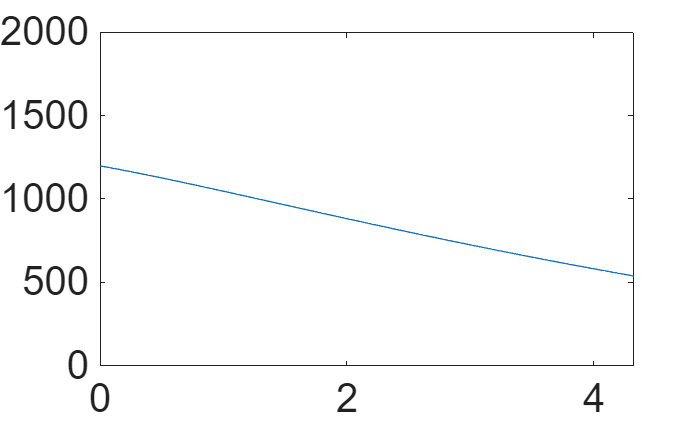

7317.1402537300

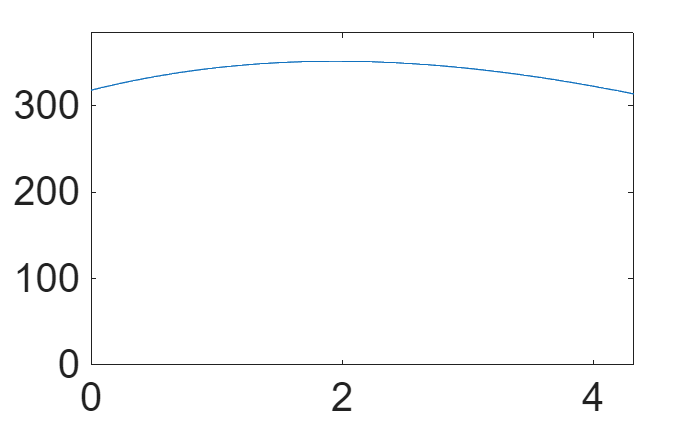

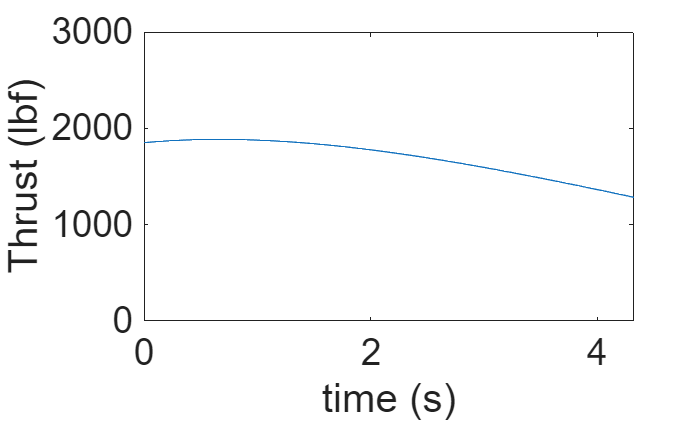

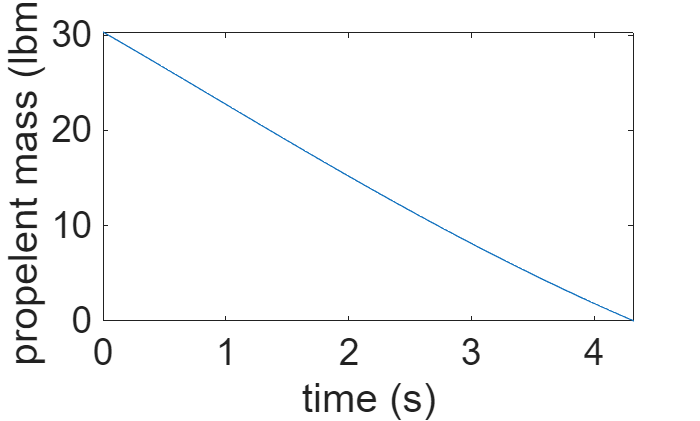

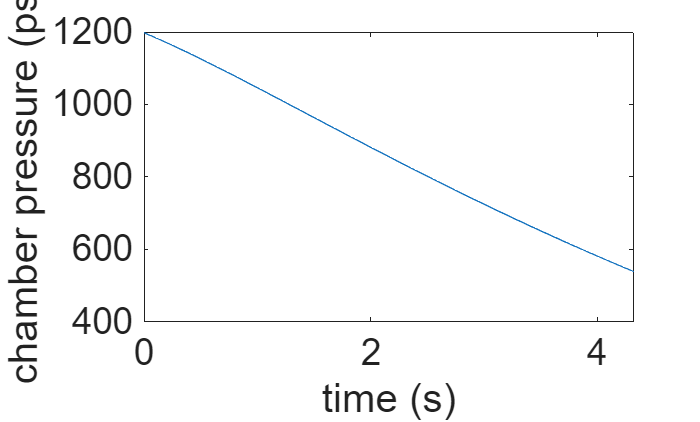

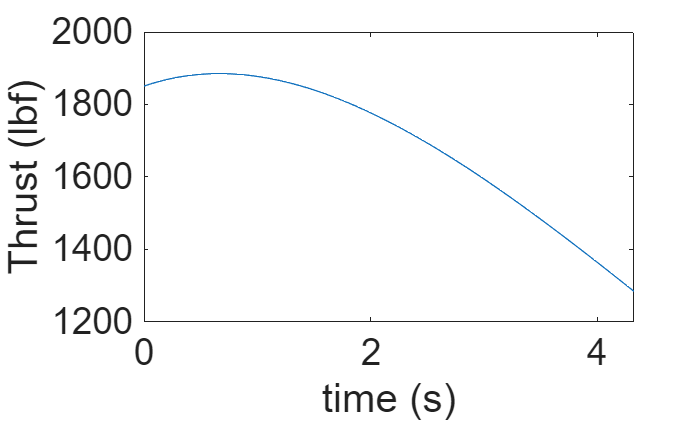



[DesignOutputs,cf,eta] = rocket(DesignInputs,DesignParameters,vacc);

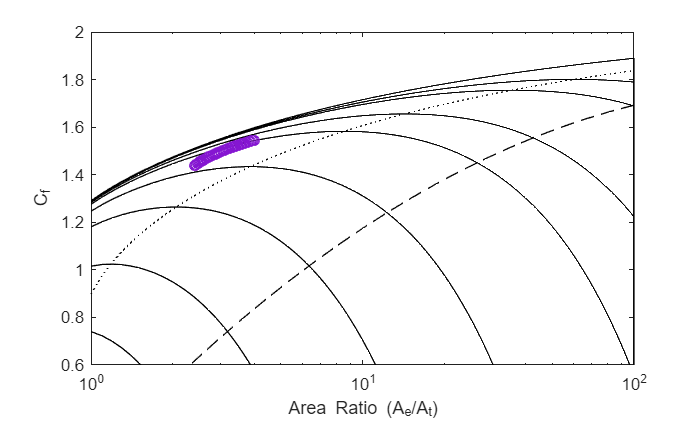

AR = 0:0.1:100;
curve1 = zeros(length(AR),1);
curve2 = zeros(length(AR),1);
curve3 = zeros(length(AR),1);
curve4 = zeros(length(AR),1);
curve5 = zeros(length(AR),1);
curve6 = zeros(length(AR),1);
curve7 = zeros(length(AR),1);
curve8 = zeros(length(AR),1);
curve9 = zeros(length(AR),1);
curve10 = zeros(length(AR),1);
ratioOfTheSpecificHeats = 1.25;

for index = 1:1000
    ratio = index/10;
    curve1(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,2);
    curve2(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,4);
    curve3(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,10);
    curve4(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,25);
    curve5(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,75);
    curve6(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,150);
    curve7(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,500);
    curve8(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,1000);
    curve9(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,100000000);
    curve10(index) = thrust_coefficient_special(ratioOfTheSpecificHeats,ratio);
end




cfmin = @(ar) -0.0445*log(ar).^2 + 0.5324.*log(ar) + 0.1843;
figure(1);
semilogx(AR,curve1,AR,curve2,AR,curve3,AR,curve4,AR,curve5,AR,curve6,AR,curve7,AR,curve8,AR,curve9,'Color','k')
hold on;
semilogx(AR,curve10,':','Color','k')
semilogx(eta,cf,'o')
fplot(cfmin,'--','Color','k');
ylim([0.6 2])
xlim([1 100])
xlabel('Area Ratio (A_e/A_t)')
ylabel('C_f')
hold off;






function [DesignOutputs,cf,eta] = rocket(DesignInputs,DesignParameters,vacc)

    w_step = 0.01;

    Cd =  [0.15 0.15 0.42 0.25 0.175];
    mCd = [0.00 0.60 1.20 1.80 4.000];

    r_i = DesignInputs(1);
    r_o = DesignInputs(2);
    l_0 = DesignInputs(3);
    Ngrain = DesignInputs(4);
    A_e0 = DesignInputs(5);
    A_t0 = DesignInputs(6);
    m_bal = DesignInputs(7);
    T_b = DesignInputs(8);

    a_0 = DesignParameters(1);
    n = DesignParameters(2);
    sigma_p = DesignParameters(3);
    gamma_p = DesignParameters(4);
    cstar = DesignParameters(5); 
    rho_p = DesignParameters(6);
    mw_air = DesignParameters(7);
    gamma_air = DesignParameters(8);
    A_rocket = DesignParameters(9);
    R_u = DesignParameters(10);
    ge = DesignParameters(11);
    

    
    if (l_0/2) < (r_o - r_i)
        wmax = l_0/2;
    else
        wmax = r_o - r_i;
    end

    w = [0:w_step:wmax wmax];
    
    A_b = Ngrain * pi .* ((r_o^2 - (r_i + w).^2)*2 + ((r_i + w)*2).*(l_0 - 2.* w));
    A_p = pi.*(r_i+w).^2;
    p_c = zeros(size(w)); p_c(1) = (a_0 * exp(sigma_p*(T_b-70)) * rho_p * A_b(1) * cstar/(ge * A_t0))^(1/(1-n));         
    A_t = zeros(size(w)); A_t(1) = A_t0;     
    r = zeros(size(w)); r(1) = a_0 * exp(sigma_p*(100-70)) * p_c(1)^n;         
    vel = zeros(size(w)); vel(1) = 0;      
    T_a = zeros(size(w)); T_a(1) = 518;     
    
    mdot = zeros(size(w)); mdot(1) = p_c(1) * A_t(1)/cstar;                   
    m_r = zeros(size(w)); m_r(1) = m_bal +    Ngrain * (r_o^2 - r_i^2) * pi * l_0 + (l_0+0.125) * Ngrain * 0.25 + 40;
    rho_air = zeros(size(w)); rho_air(1) = 0.07579;
    mach = zeros(size(w)); mach(1) = 0;
    eta = zeros(size(w)); eta(1) = A_e0/A_t(1);
    acc = zeros(size(w)); acc(1) = 0;
    height = zeros(size(w)); height(1) = 0;
    p_a = ones(size(w)); 
    
        if vacc == 1
            p_a(1) = 0.0000000000000000000000000000000000000000000000001;
        elseif vacc == 2
            p_a(1) = 14.69241;
        else
            p_a(1) = -4.272981E-14*height(1)^3 + 0.000000008060081*height(1)^2 - 0.0005482655*height(1) + 14.69241; 
        end

    m_p = pi.*(r_o^2 - (r_i+w).^2).* rho_p .* (l_0 - 2.*w) .* Ngrain;
    time = zeros(size(w)); 
    F_t = zeros(size(w)); F_t(1) = thrust_coefficient(gamma_p,eta(1),p_c(1)/p_a(1)) * A_t(1) * p_c(1);
    I = zeros(size(w)); 
    d = ones(size(w)); d(1) = sqrt(A_t0*4/pi);
    cf = zeros(size(w)); cf(1) = thrust_coefficient(gamma_p,eta(1),p_c(1)/p_a(1));
  
    for i = 1:(length(w)-1)
        
        
        
        p_c(i) = (a_0* exp(sigma_p*(T_b-70)) * rho_p * A_b(i) * cstar/(ge * A_t(i)))^(1/(1-n));

        

        p_c(end) = (a_0* exp(sigma_p*(T_b-70)) * rho_p * A_b(end) * cstar/(ge * A_t(end)))^(1/(1-n));

        mdot(i+1) =  p_c(i)* A_t(i)/cstar;

        r(i+1) = a_0 * exp(sigma_p*(T_b-70)) * p_c(i)^n;

        time(i+1) = time(i) + (w(i+1)-w(i))/r(i+1);

        d(i+1) = d(i) + 0.000087 * (time(i+1) - time(i)) * p_c(i);

        A_t(i+1) = pi * 0.25 * d(i+1) * d(i+1);

        eta(i) = A_e0/A_t(i);

        mach(i+1) = vel(i)/sqrt(gamma_air * R_u/mw_air * T_a(i));

        acc(i+1) = F_t(i)/m_r(i) - ge - interp1(mCd,Cd,mach(i),'linear','extrap') * 0.5 * rho_air(i) * vel(i)^2 * A_rocket/m_r(i);

        vel(i+1) = (acc(i+1) + acc(i))/2 * (time(i+1) - time(i));

        height(i+1) = 0; %(vel(i+1) + vel(i))/2 * (time(i+1) - time(i));

        rho_air(i+1) = 0.00000000001255* height(i)^2 - 0.0000019453*height(i) + 0.07579;

        if vacc == 1
            p_a(i+1) = 0.0000000000000000000000000000000000000000000000001;
        elseif vacc == 2
            p_a(i+1) = 14.69241;
        else
            p_a(i+1) = -4.272981E-14*height(i)^3 + 0.000000008060081*height(i)^2 - 0.0005482655*height(i) + 14.69241; %0.000000000000000000001; 
        end

        F_t(i) = p_c(i) * A_t(i) * thrust_coefficient(gamma_p,eta(i),p_c(i)/p_a(i));

        cf(i+1) = thrust_coefficient(gamma_p,eta(i),p_c(i)/p_a(i));

        

        T_a(i+1) = -0.0036*height(i) + 518;

        %        balast mass             mass of the grains                         case mass                   baseline mass
        m_r(i+1) = (m_bal +    Ngrain * (r_o^2 - (r_i)^2) * pi * l_0 *rho_p + (l_0+0.125) * Ngrain * 0.25 + 40) - mdot(i)*(time(i+1) - time(i));

    end
  
    d(end) = d(end-1) + 0.000087 * (time(end) - time(end-1)) * p_c(end-1);
    A_t(end) = pi * 0.25 * d(end) * d(end);
              
    p_c(end) = (a_0* exp(sigma_p*(T_b-70)) * rho_p * A_b(end) * cstar/(ge * A_t(end)))^(1/(1-n));
    eta(end) = A_e0/A_t(end);
    F_t(end) = p_c(end) * A_t(end) * thrust_coefficient(gamma_p,eta(end),p_c(end)/p_a(end));

    for i = 1:(length(w)-1)

    I(i+1) = ( F_t(i+1) + F_t(i) )/2 * (time(i+1) - time(i));

    end

    I_total = sum(I);
    fprintf('%10.10f',I_total)
    Isp = I_total/m_p(1);

    
   

    figure(1)
    plot(time,p_c)
  
    ylim([0 2000])
    ax = gca; % current axes
    ax.FontSize = 24;

    figure(2)
    plot(time,A_b)
  
    ylim([0 385])
    ax = gca; % current axes
    ax.FontSize = 24;
    

    figure(3)
    plot(time,F_t)
   
    xlabel('time (s)')
    ylabel('Thrust (lbf)')
    ylim([0 3000]);
    ax = gca; % current axes
    ax.FontSize = 22;
    

    figure(4)
    plot(time,m_p)
    xlabel('time (s)')
    ylabel('propelent mass (lbm)')
    ax = gca; % current axes
    ax.FontSize = 22;
  

    figure(5)
    plot(time,p_c)
    xlabel('time (s)')
    ylabel('chamber pressure (psi)')
    ax = gca; % current axes
    ax.FontSize = 22;
   

    figure(6)
    plot(time,F_t)
    xlabel('time (s)')
    ylabel('Thrust (lbf)')
    ax = gca; % current axes
    ax.FontSize = 22;
    


      
  

    DesignOutputs = [Ngrain * (r_o^2 - r_i^2) * pi * l_0*rho_p 
        A_t(end)
        time(end)
        Isp
        max(p_c)
        max(F_t)
        A_p(1)/A_t(1)
        max(w)];

end


function [cf] = thrust_coefficient(gamma, areaRatio, pcpa)

    [~,mach] = machNumbers(areaRatio,gamma);

    papc = 1/pcpa;
    pepc = (1+ (gamma-1)/2 * mach^2 )^(-gamma/(gamma-1));

    one = (2*gamma^2)/(gamma-1);
    two = (2/(gamma+1))^((gamma+1)/(gamma-1));
    three = (1 - pepc^((gamma-1)/gamma));
    four = sqrt(one*two*three);
    five = (pepc-papc)*areaRatio;
    cf = four + five;
end

function [cf] = thrust_coefficient_special(gamma,areaRatio)
% Calculate the thrust coefficient using the given parameters
    [~,mach] = machNumbers(areaRatio,gamma);

    pcpe = (1+ (gamma-1)/2*mach^2)^(gamma/(gamma-1));

    pepc = pcpe^(-1);

    papc = pepc;

    cf = (2*gamma^2/(gamma-1)*(2/(gamma+1))^((gamma+1)/(gamma-1))*(1-pepc^((gamma-1)/gamma)))^0.5 + (pepc - papc)*areaRatio;
end

function [M_sub, M_super] = machNumbers(areaRatio, gamma)
% machNumbers - Computes the subsonic and supersonic Mach numbers
% corresponding to a given area ratio A/A*

    f = @(M) (1./M) .* ( (2/(gamma+1)) .* (1 + (gamma-1)/2 .* M.^2) ) ...
        .^((gamma+1)/(2*(gamma-1))) - areaRatio;

    try
        M_sub = fzero(f, [1e-6, 0.999]); 
    catch
        M_sub = NaN; 
    end

    try
        M_super = fzero(f, [1.0001, 50]); 
    catch
        M_super = NaN;
    end
end
